# **Evaluación 1 | Procesamiento de señales e imágenes 2023-1**

*Estudiante: Nícolas Farfán Cheneaux*

*Profesor: Max Chacón*

*Ayudante: Luis Corral*

### Pregunta 1

Para calcular la frecuencia alias (fa) usando herramientas del dominio del tiempo, se seguirán los siguientes pasos:

1) Identificar los picos de la señal con la función **findpeaks.**

2) Calcular la distancia en tiempo entre los picos de la señal.

3) Se obtiene el **periodo** y a partir de este, la **frecuencia**.

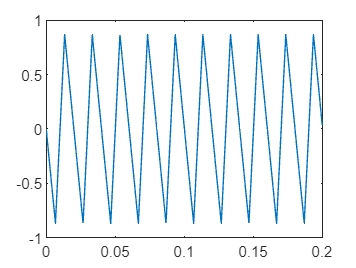

% Se lee el archivo de audio de la señal
[x_n,Fs] = audioread('senal_1.wav');

% Visualizar la señal en el dominio del tiempo
d = length(x_n)/Fs;
t = linspace(0, d,length(x_n));
figure;
plot(t,x_n);
xlim([0 0.2]); % Se acota para visualizar de manera clara


% Calculo de la frecuencia alias usando herramientas del domino del tiempo (fa)

% Se indentifican los picos de la señal
[pks, locs] = findpeaks(x_n);

% Se calcula la distancia en el tiempo entre los picos de la señal
time_diff = diff(locs)/Fs;
periodo = mean(time_diff)

periodo =    0.020000000000000



% Se obtiene la frecuencia de la señal
fa = 1/periodo;
disp(['La frecuencia alias de la señal es ', num2str(fa), ' Hz']);

La frecuencia alias de la señal es 50 Hz


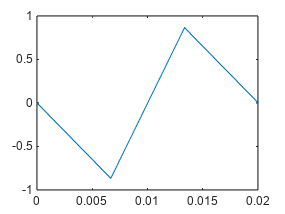


% Gráficamente podemos comprobar viendo un periodo de la señal
plot(t,x_n);
xlim([0 periodo]);


% Calculo de la frecuencia muestreada originalmente (f)
% f = |fa - Fs [fa / Fss]|
f = abs(fa - Fs*ceil(fa/Fs))

f =      1.000000000000000e+02


disp(f)

     1.000000000000000e+02



disp(['La frecuencia original es ', num2str(f), ' Hz']);

La frecuencia original es 100 Hz


### Pregunta 2

Se tiene la función Transferencia del sistema H(z):

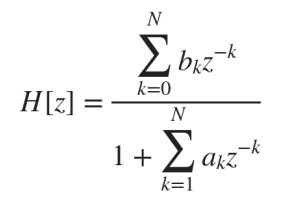

Se desarrolla la sumatoria y se obtienen los siguientes coeficientes:

H(z) = $\frac{b_0 z^0 +b_1 z^{-1} +b_2 z^{-2} }{1+a_1 z^{-1} +a_2 z^{-2} }=\frac{b_0 z^2 +b_1 z^1 +b_2 z^0 }{z^2 +a_1 z^1 +a_2 z^0 }$

clearvars
[y_n,Fs2] = audioread('1kHz_44100Hz_16bit_05sec.wav'); % Lectura del archivo de la señal
n = -5:5

n =     -5    -4    -3    -2    -1     0     1     2     3     4     5


Fs2 % Frecuencia de muestreo

Fs2 =        44100


Fc = 800 % Frecuencia de corte del filtro

Fc =    800


Fr = Fs2 / Fc

Fr =   55.125000000000000


x_n = n == 0

x_n = 1×11 logical array
   0   0   0   0   0   1   0   0   0   0   0



% Función de transferencia
% Dado que H[z] = Y[z] / X[z]

% Cálculo de los coeficientes numerador
a1 = (2*(tan(pi/Fr)^2-1)) / (1 + (2*cos(pi/4)*tan(pi/Fr)+tan(pi/Fr)^2))

a1 =   -1.839116797325203


a2 = (1-2*cos(pi/4)*tan(pi/Fr)+tan(pi/Fr)^2)/(1+2*cos(pi/4)*tan(pi/Fr)+tan(pi/Fr)^2)

a2 =    0.851128341245972



% Cálculo de los coeficientes denominador
b2 = (tan(pi/Fr)^2)/(1+2*cos(pi/4)*tan(pi/Fr)+tan(pi/Fr)^2)

b2 =    0.003002885980192


b0 = b2

b0 =    0.003002885980192


b1 = 2*b0

b1 =    0.006005771960384



% Vector de coeficientes numerador
b = [b0 b1 b2]

b =    0.003002885980192   0.006005771960384   0.003002885980192



% Vector de coeficientes denominador
a = [1 a1 a2]

a =    1.000000000000000  -1.839116797325203   0.851128341245972



% Obtención de la salida del sistema y[n]
y_n = filter(b, a, x_n)

y_n =                    0                   0                   0                   0                   0   0.003002885980192   0.011528430007008   0.021649173889597   0.030003185839537   0.036753137588764   0.042056750898201



% Obtención de la respuesta al impulso h[n]
h_n = impz(b, a, n)

h_n =                    0
                   0
                   0
                   0
                   0
   0.003002885980192
   0.011528430007008
   0.021649173889597
   0.030003185839537
   0.036753137588764


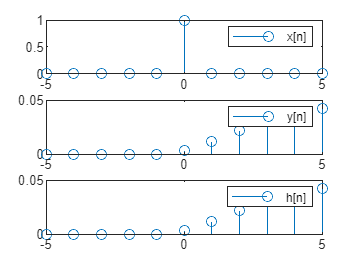


% Gráfico
subplot(3, 1, 1)
stem(n, x_n)
legend('x[n]')
subplot(3, 1, 2)
stem(n, y_n)
legend('y[n]')
subplot(3, 1, 3)
stem(n, h_n)
legend('h[n]')

### Pregunta 3

Se aplica la transforamda Z a la ecuación de diferencias y se obtiene lo siguiente


$$\begin{array}{l}
y\left\lbrack n\right\rbrack =x\left\lbrack n\right\rbrack +\alpha y\left\lbrack n-1\right\rbrack \\
Y\left(z\right)=X\left(z\right)+{\alpha Y\left(z\right)}^{-1} z\\
Y\left(z\right)\;\left(1-\alpha z^{-1} \right)=X\left(z\right)
\end{array}$$


Función Transferencia del sistema H(z)

H(z) = $\frac{Y\left(z\right)}{X\left(z\right)}=\frac{1}{1-\alpha z^{-1} }=\frac{z}{z-\alpha \;}$

clearvars
% Valor de alpha definido
alpha = 0.6

alpha =    0.600000000000000



% Vector de coeficientes numerador
b = [1 0]

b =      1     0



% Vector de coeficientes denominador
a = [1 -alpha]

a =    1.000000000000000  -0.600000000000000


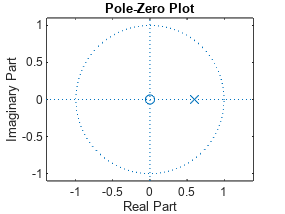


% Gráfico
figure
zplane(b, a)


% Column vectors
%z = 0 % Zeros
%p = alpha % Poles
%figure 
%zplane(z, p)

### Análisis del diagrama de polos y ceros

Como se puede apreciar en el diagrama de polos y ceros, tenemos un cero en el origen y un polo con **parte real positiva**, por lo tanto el sistema es **inestable**.